# Assignment 12: Color Measurement

*Pratheep Kumar Chelladurai*

Github Link: [https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%2012%20Color%20Measurements](https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%2012%20Color%20Measurements)

In this assignment, I have used a "virtual spectrophotometer" to make some color measurements. 

% Reading the Dataset
warning('off','all');
all_patches = readtable("color_science_lab_measurements.csv",'Range','B1:AP17');
blue_patch37_dataset = readtable("Blue37_Patch.csv",'Range','B1:AP11');
source_dataset = readtable("Illuminant Data.xlsx");
xyz_std_obs_two_deg_dataset = readtable("StdObsFuncs.xlsx",Sheet="2-degree");


%Formatting the dataset (as needed)
wavelength_info = 360:10:750;
bluish_grey_patches = all_patches{2:6,2:end};
grey_patches = all_patches{7:11,2:end};
orange_patches = all_patches{12:16,2:end};
blue_patch37 = blue_patch37_dataset{2:11,2:end};

xyz_std_obs_two_deg = interp1(xyz_std_obs_two_deg_dataset{:,1},...
    xyz_std_obs_two_deg_dataset{:,2:end},wavelength_info,"linear","extrap");
source_D65 = interp1(source_dataset{:,1},source_dataset.D65,...
    wavelength_info,"linear","extrap");

## Question 1

*Make measurements of at least 10 samples of your choice; you can download the data from the Simulator application. ******OR****** Use the real spectrophotometer to measure 10 real samples of your choice. Please create a plot (or multiple plots) of the reflectance curves for your measurements and label them clearly.*

#### **Answer:** 

I have used simulator application to measure the samples. I picked 15 samples and plotted into 3 sets of 5 samples. Set 1 consist of patch 31 to patch 35 which visually matches towards bluish grey. Set 2 consist of grey patches from patch 19 to patch 23. And the 3rd set was randomly chosen which matches closer to orange color (patches 12, 16, 28, 38, 39)

*(Please find the measured dataset from the "****color_science_lab_measurements.csv****" file)*

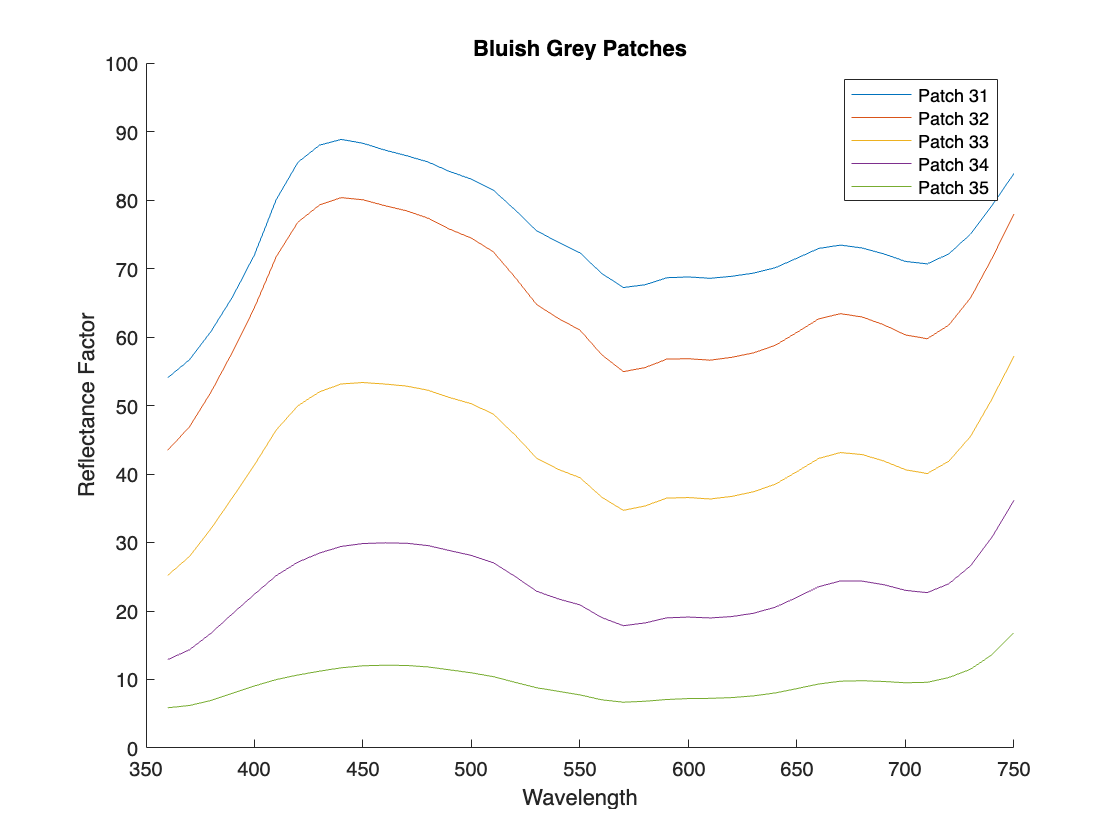

figure(1);
hold on
line(wavelength_info,bluish_grey_patches);
legend('Patch 31','Patch 32','Patch 33','Patch 34','Patch 35')
xlabel('Wavelength');
ylabel('Reflectance Factor');
ylim([0,100])
title('Bluish Grey Patches')
hold off

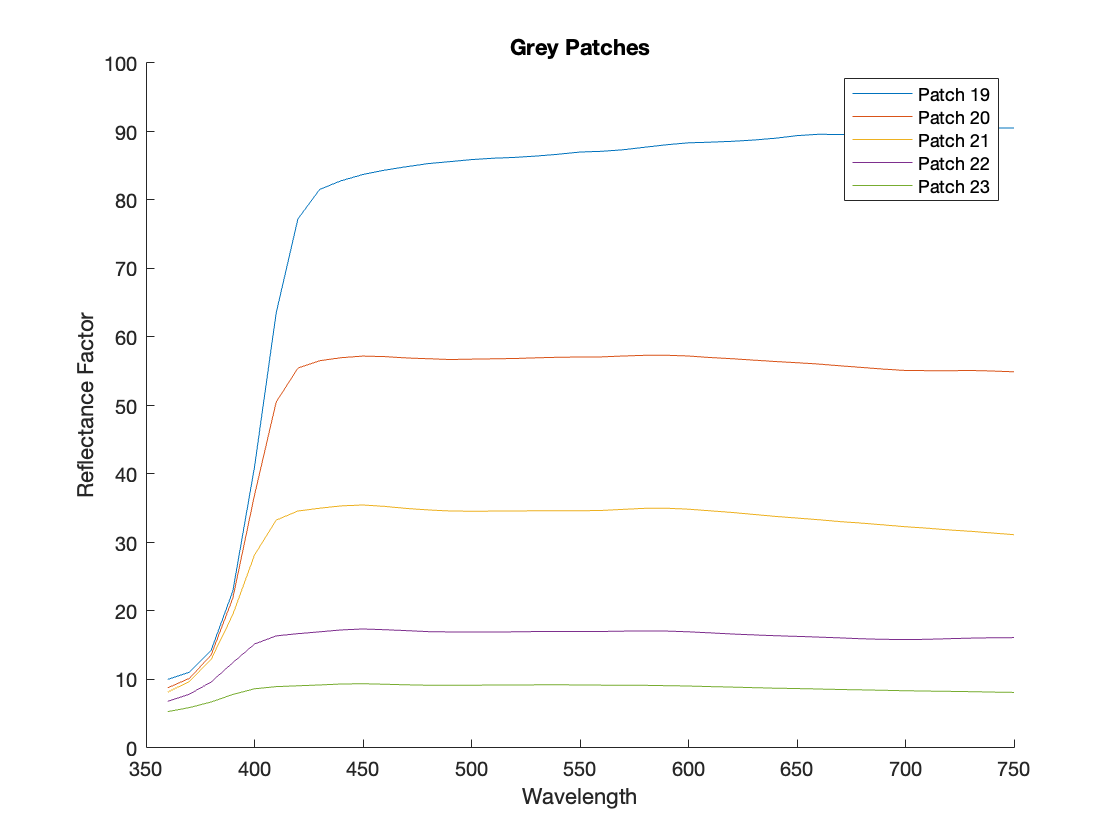

figure(2);
hold on
line(wavelength_info,grey_patches);
legend('Patch 19','Patch 20','Patch 21','Patch 22','Patch 23')
xlabel('Wavelength');
ylabel('Reflectance Factor');
title('Grey Patches')
hold off

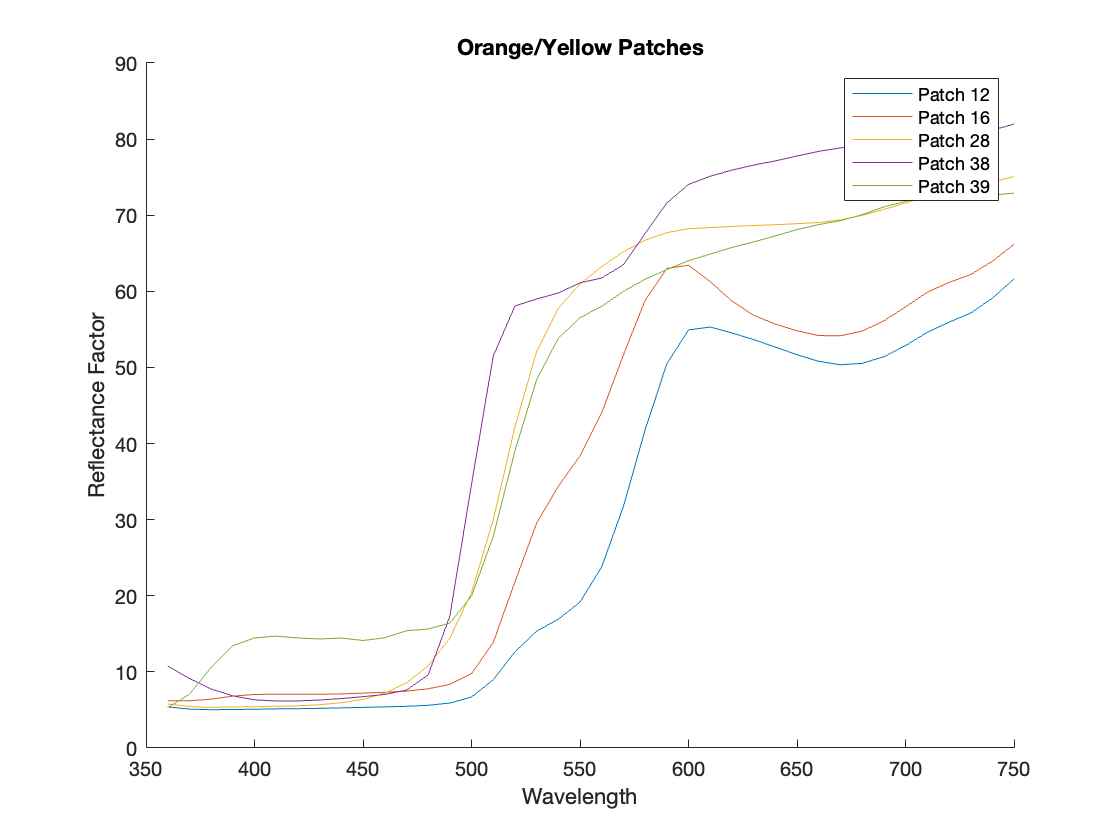

figure(3);
hold on
line(wavelength_info,orange_patches);
legend('Patch 12','Patch 16','Patch 28','Patch 38','Patch 39')
xlabel('Wavelength');
ylabel('Reflectance Factor');
title('Orange/Yellow Patches')
hold off

## Question 2

*Using either the real or simulated spectrophotometer, please make 10 measurements of a single Macbeth ColorChecker test target patch (please choose from patches #1-24). If you have access to a real spectrophotometer, please make 10 measurements of a single sample**** with replacement****. Make a plot showing all of these curves together.*

#### **Answer:** 

For this measurement as well, I have used simulator application to do repeated measure of the sample. I chose the color patch 37 (visually blue color) for this data collection. I measured the mentioned sample 10 times with replacement each time. Following image shows the spectrophotometer simulator used for the data collection.

*(Please find the measured dataset from the "****Blue37_Patch.csv****" file)*

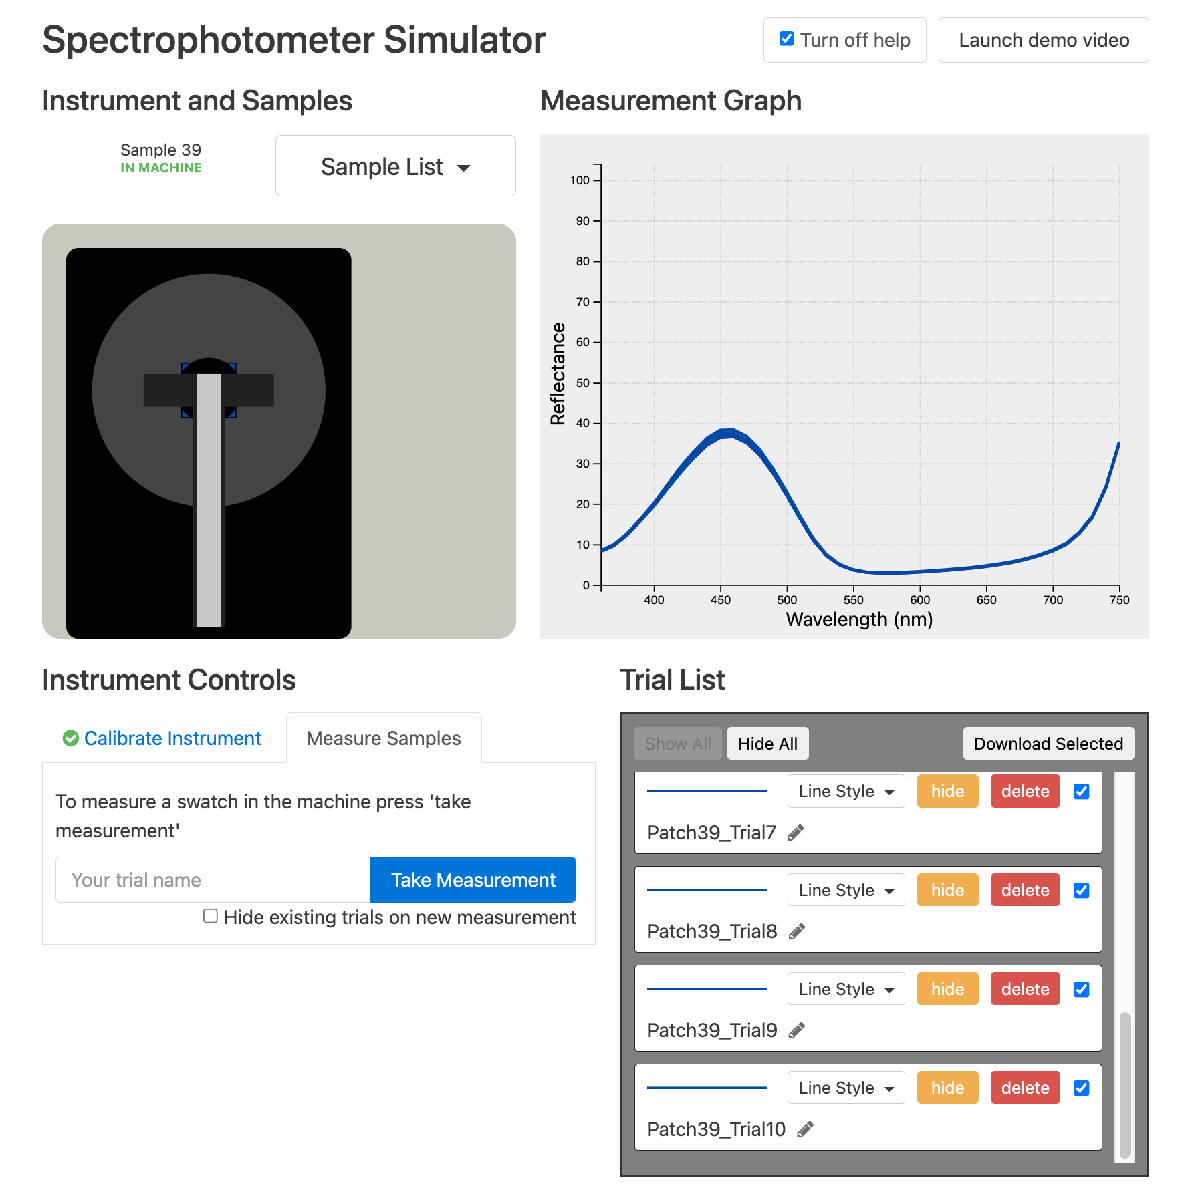

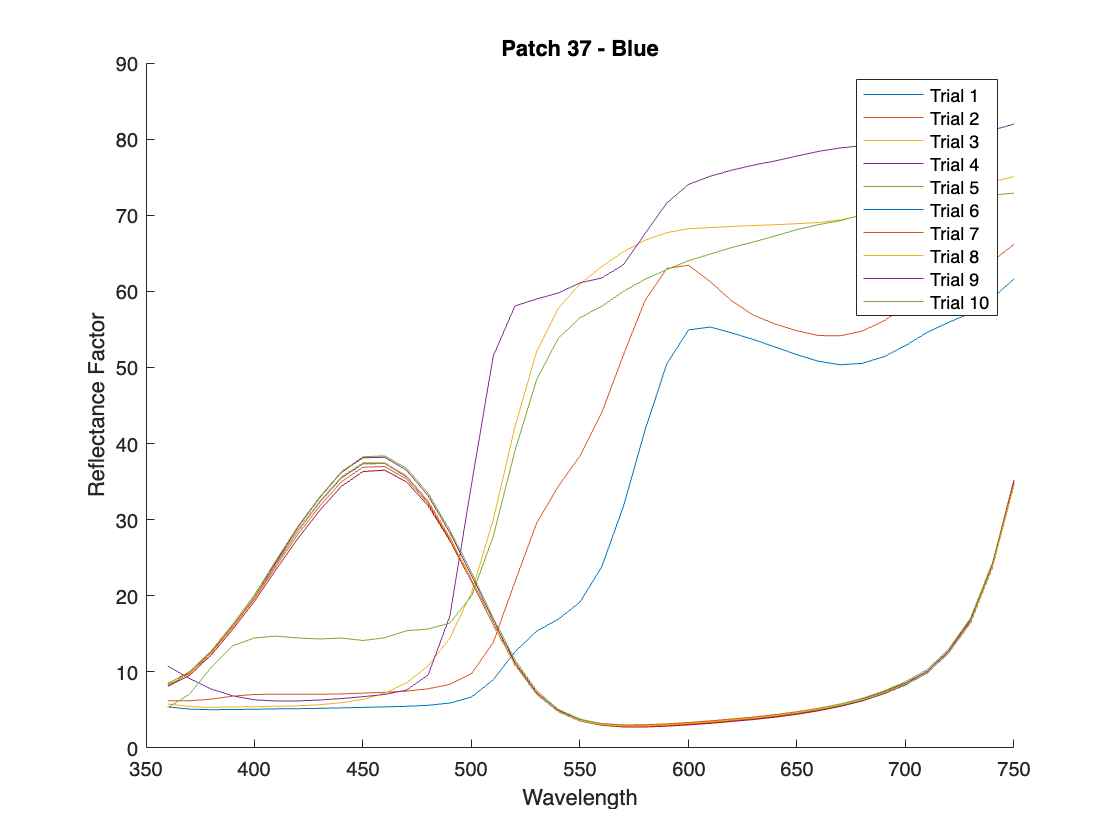

figure(4);
hold on
line(wavelength_info,blue_patch37);
xlabel('Wavelength');
ylabel('Reflectance Factor');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6',...
    'Trial 7','Trial 8','Trial 9','Trial 10')
title('Patch 37 - Blue')
hold off

## Question 3

*Using the data for the patch that you measured ten times, calculate CIELAB values under D65, using the CIE 1931 standard observer. Evaluate the precision of the measurements by calculating the MCDM from the measured CIELAB values.*

% White point value of Source D65 for 2 degree observer
wp_D65_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,...
    source_D65,10);


% Tristimulus value for Patch 37 in D65 Source for 2 degree observer
tristimulus_XYZ_blue_patch37 = calcTristimulus(xyz_std_obs_two_deg,...
    source_D65,blue_patch37',10);


%Calculate CIELAB for Patch 37 in D65 Source for 1931 std observer
[L_blue_patch37, a_blue_patch37, b_blue_patch37, C_blue_patch37] = ...
    calcXYZtoCIELAB(tristimulus_XYZ_blue_patch37,wp_D65_two_deg_source);
CIELAB_blue_patch37 = [L_blue_patch37; a_blue_patch37; b_blue_patch37; ...
    C_blue_patch37];
table_CIELAB_blue_patch37 = createTableCIELAB(CIELAB_blue_patch37)

table_CIELAB_blue_patch37 = 10×4 table
      L         a          b         C   
    ______    ______    _______    ______

    209.32    84.576    -254.07    267.78
    211.14    85.863    -254.13    268.24
    211.19    85.164     -257.9     271.6
    211.23    85.204    -257.82    271.53
    212.67     82.07    -256.51    269.32
    208.43    81.556    -252.67     265.5
    208.39    81.573    -252.67    265.51
    209.32     87.08     -256.4    270.79
    209.32    84.576    -254.07    267.78
    209.81    87.319    -256.12    270.59


%MCDM Calculation
MCDM_blue_patch37 = calcMCDM(CIELAB_blue_patch37(1,:),...
    CIELAB_blue_patch37(2,:),CIELAB_blue_patch37(3,:)) 

MCDM_blue_patch37 = 2.8873

Mean color difference from the mean (MCDM) is a radius of the confidence ellipsoid with 95% confidence limit. The MCDM value is found to be **2.8873 **for the repeated measure of the patch. 

## Functions

function mcdm = calcMCDM(L_star,a_star,b_star)
    L_star_mean = mean(L_star);
    a_star_mean = mean(a_star);
    b_star_mean = mean(b_star);
    n = numel(L_star);
    mcdm = (sum(((L_star-L_star_mean).^2+(a_star-a_star_mean).^2+...
        (b_star-b_star_mean).^2).^(1/2)))./n;
end


%Function to create table and assign CIELAB values
function a2t = createTableCIELAB(values)
    a2t = array2table(values');
    a2t.Properties.VariableNames(1:4) = {'L','a','b','C'};
end


%Function to calculate CIELAB from XYZ
function [L_star,a_star,b_star,C_star] = calcXYZtoCIELAB(XYZ,whitepoint)
    XYZ_Prime = calcXYZPrime(XYZ,whitepoint);
    L_star = (116 * calConstants(XYZ_Prime(2,:))) - 16;
    a_star= 500*(calConstants(XYZ_Prime(1,:)) - calConstants(XYZ_Prime(2,:)));
    b_star = 200*(calConstants(XYZ_Prime(2,:)) - calConstants(XYZ_Prime(3,:)));
    C_star = ((a_star).^2 + (b_star).^2).^(1/2);
end


% Calculate X Prime, Y Prime and Z Prime
function XYZ_Prime = calcXYZPrime(XYZ,whitepoint)
    XYZ_Prime = XYZ./whitepoint';
end


%Function to calculate constants in a and b
function k = calConstants(x)
    if (x > (24/116)^3)
        k = (x).^(1/3);
    else
        k = ((841/108).*x) + (16/116);
    end
end

%Function to calculate Tristimulus values for materials
function t = calcTristimulus(xyz_value,source,material,d_lambda)   

    %Calculate normalizing constant
    k = (100/(source * xyz_value(:,2) * d_lambda))/100;

    s_lambda = diag(source);

    %Calculating tristimulus
    t = k.*((s_lambda*xyz_value)'*material)*d_lambda;

%   t = custom_normalization(t);
end


%Function to calculate Tristimulus values for sources (Whitepoint)
function ts = calcTristimulusSource(xyz_value,source,d_lambda)   

    %Calculate normalizing constant
    k = (100/(source * xyz_value(:,2) * d_lambda))/100;

    %Calculating tristimulus
    ts = k.*((source*xyz_value))*d_lambda;

%   t = custom_normalization(t);
end